%清空变量
warning off
close all
clear, clc

%% 加载数据
data_all=readtable('D:\桌面\论文材料\RAMAN第二次实验\第四次\插值过程标签光谱.xlsx');%数据增强数据集
% data_all = removevars(data_all, {'x____h_', 'Var7'});
data_all = table2array(data_all);
[row, colm] = size(data_all);
n_substance = 3;
n = size(data_all, 1); % 测试集大小

%% 训练集和测试集划分
temp = randperm(row); % 产生随机排列
train_x = data_all(temp(1:row), 4:end)'; % 训练集样本特征
train_y = data_all(temp(1:row), n_substance)'; % 训练集样本标签
test_x = data_all(:, 4:end)'; % 测试集样本特征
test_y = data_all(:, n_substance)'; % 测试集样本标签

[x_transform, m] = size(train_x); % 特征维度和样本数
n = size(test_x, 2); % 测试集样本数


data_allp=readtable('D:\桌面\论文材料\RAMAN第二次实验\过程光谱拟合标签+预处理.xlsx');%数据增强数据集
datap = table2array(data_allp)

datap =     8.5476    0.0000   77.9172    0.0837    0.0000   -0.0663   -0.0651   -0.0709   -0.0752   -0.0752   -0.0750   -0.0783   -0.0846   -0.0909   -0.0940   -0.0933   -0.0906   -0.0894   -0.0924   -0.1001   -0.1098   -0.1159   -0.1120   -0.0925   -0.0545    0.0009    0.0690    0.1416    0.2099    0.2656    0.3032    0.3193    0.3179    0.3050    0.2876    0.2722    0.2618    0.2558    0.2512    0.2452    0.2364    0.2255    0.2141    0.2049    0.1983    0.1927    0.1858    0.1771    0.1687    0.1629
    8.6406    0.0000   78.3133    0.0873    0.0000   -0.0657   -0.0660   -0.0718   -0.0755   -0.0751   -0.0749   -0.0784   -0.0850   -0.0913   -0.0944   -0.0935   -0.0906   -0.0893   -0.0923   -0.0999   -0.1095   -0.1157   -0.1118   -0.0924   -0.0546    0.0006    0.0683    0.1406    0.2087    0.2644    0.3023    0.3189    0.3182    0.3060    0.2891    0.2739    0.2634    0.2566    0.2513    0.2444    0.2351    0.2237    0.2124    0.2036    0.1975    0.1922    0.1857    0.1769    0.1683 

x_porecess=datap(:,6:end)'

x_porecess =    -0.0663   -0.0657   -0.0648   -0.0660   -0.0650   -0.0663   -0.0656   -0.0646   -0.0649   -0.0658   -0.0660   -0.0655   -0.0650   -0.0661   -0.0667   -0.0659   -0.0660   -0.0665   -0.0658   -0.0667   -0.0665   -0.0665   -0.0656   -0.0665   -0.0663   -0.0662   -0.0661   -0.0661   -0.0670   -0.0663   -0.0673   -0.0665   -0.0667   -0.0664   -0.0670   -0.0655   -0.0662   -0.0674   -0.0654   -0.0654   -0.0665   -0.0665   -0.0664   -0.0672   -0.0660   -0.0663   -0.0664   -0.0669   -0.0663   -0.0666
   -0.0651   -0.0660   -0.0656   -0.0667   -0.0662   -0.0658   -0.0651   -0.0674   -0.0654   -0.0664   -0.0666   -0.0665   -0.0666   -0.0657   -0.0655   -0.0663   -0.0673   -0.0662   -0.0666   -0.0662   -0.0659   -0.0662   -0.0667   -0.0662   -0.0660   -0.0661   -0.0663   -0.0661   -0.0664   -0.0666   -0.0664   -0.0665   -0.0672   -0.0667   -0.0659   -0.0664   -0.0667   -0.0676   -0.0654   -0.0650   -0.0656   -0.0661   -0.0664   -0.0658   -0.0664   -0.0661   -0.0664   -0.0655   -0.

y_porcess=datap(:,n_substance)'

y_porcess =    77.9172   78.3133   78.6888   79.0442   79.3802   79.6972   79.9958   80.2764   80.5398   80.7863   81.0166   81.2312   81.4306   81.6153   81.7859   81.9430   82.0871   82.2186   82.3383   82.4465   82.5438   82.6309   82.7082   82.7762   82.8355   82.8867   82.9302   82.9667   82.9966   83.0205   83.0390   83.0525   83.0617   83.0670   83.0690   83.0683   83.0653   83.0607   83.0549   83.0485   83.0421   83.0361   83.0312   83.0278   83.0266   83.0279   83.0325   83.0408   83.0533   83.0704



%% 数据归一化
[train_x, train_ps] = mapminmax(train_x);
test_x = mapminmax('apply', test_x, train_ps);
x_porecess = mapminmax('apply', x_porecess, train_ps);

[train_y, output_ps] = mapminmax(train_y);
test_y = mapminmax('apply', test_y, output_ps);

trainD = reshape(train_x, [x_transform, 1, 1, n]);%训练集输入
testD = reshape(test_x, [x_transform, 1, 1, n]);%测试集输入
x_porecessD =  reshape(x_porecess,[size(x_porecess,1),1, 1,size(x_porecess,2)]);
targetD = train_y;%训练集输出
targetD_test = test_y;%测试集输出


%% 搭建CNN网络
layers = [
    imageInputLayer([x_transform 1 1]) %输入层参数设置
    convolution2dLayer([5,1], 256,'Padding', 'same')
    reluLayer
    maxPooling2dLayer([5,1], 'Stride', 2)
    convolution2dLayer([3,1], 128,'Padding', 'same')
    reluLayer
    maxPooling2dLayer([3,1], 'Stride', 2)
    fullyConnectedLayer(256)
    reluLayer
    fullyConnectedLayer(256)
    reluLayer
    fullyConnectedLayer(64) % 384 全连接层神经元
    dropoutLayer(0.8, "Name", "dropout")
    fullyConnectedLayer(1) % 输出层神经元
    regressionLayer];
%analyzeNetwork(layers)

%% 模型配置
options = trainingOptions("adam", ...
    'MiniBatchSize', 50, ...
    "MaxEpochs", 10, ...
    "InitialLearnRate", 1e-3, ...
    "LearnRateDropFactor", 0.1, ...
    "LearnRateDropPeriod", 20, ...
    "Shuffle", "every-epoch", ...
    "Plots","training-progress", ...
    "Verbose", true, ...
    'ValidationData',{testD,targetD_test'});

在单 CPU 上训练。
正在初始化输入数据归一化。


｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量　ＲＭＳＥ　　｜　　验证　ＲＭＳＥ　　｜　　小批量损失　　｜　　验证损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


｜　　　１　｜　　　　１　｜　　　　　００：００：０８　｜　　　　　　　０．８８　｜　　　　　　４．２４　｜　　０．３８５０　｜　８．９７０５　｜　　０．００１０　｜


｜　　　２　｜　　　５０　｜　　　　　００：０１：００　｜　　　　　　　０．５２　｜　　　　　　０．４３　｜　　０．１３４０　｜　０．０９０９　｜　　０．００１０　｜


｜　　　４　｜　　１００　｜　　　　　００：０１：５５　｜　　　　　　　０．３６　｜　　　　　　０．２８　｜　　０．０６６４　｜　０．０３８６　｜　　０．００１０　｜


｜　　　６　｜　　１５０　｜　　　　　００：０２：４９　｜　　　　　　　０．２５　｜　　　　　　０．１９　｜　　０．０３０２　｜　０．０１７９　｜　　０．００１０　｜


｜　　　８　｜　　２００　｜　　　　　００：０３：４４　｜　　　　　　　０．３２　｜　　　　　　０．１９　｜　　０．０５２５　｜　０．０１８０　｜　　０．００１０　｜


｜　　１０　｜　　２５０　｜　　　　　００：０４：３９　｜　　　　　　　０．３１　｜　　　　　　０．１４　｜　　０．０４９５　｜　０．０１０４　｜　　０．００１０　｜


｜　　１０　｜　　２６０　｜　　　　　００：０４：５６　｜　　　　　　　０．２７　｜　　　　　　０．１４　｜　　０．０３６０　｜　０．０１０１　｜　　０．００１０　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


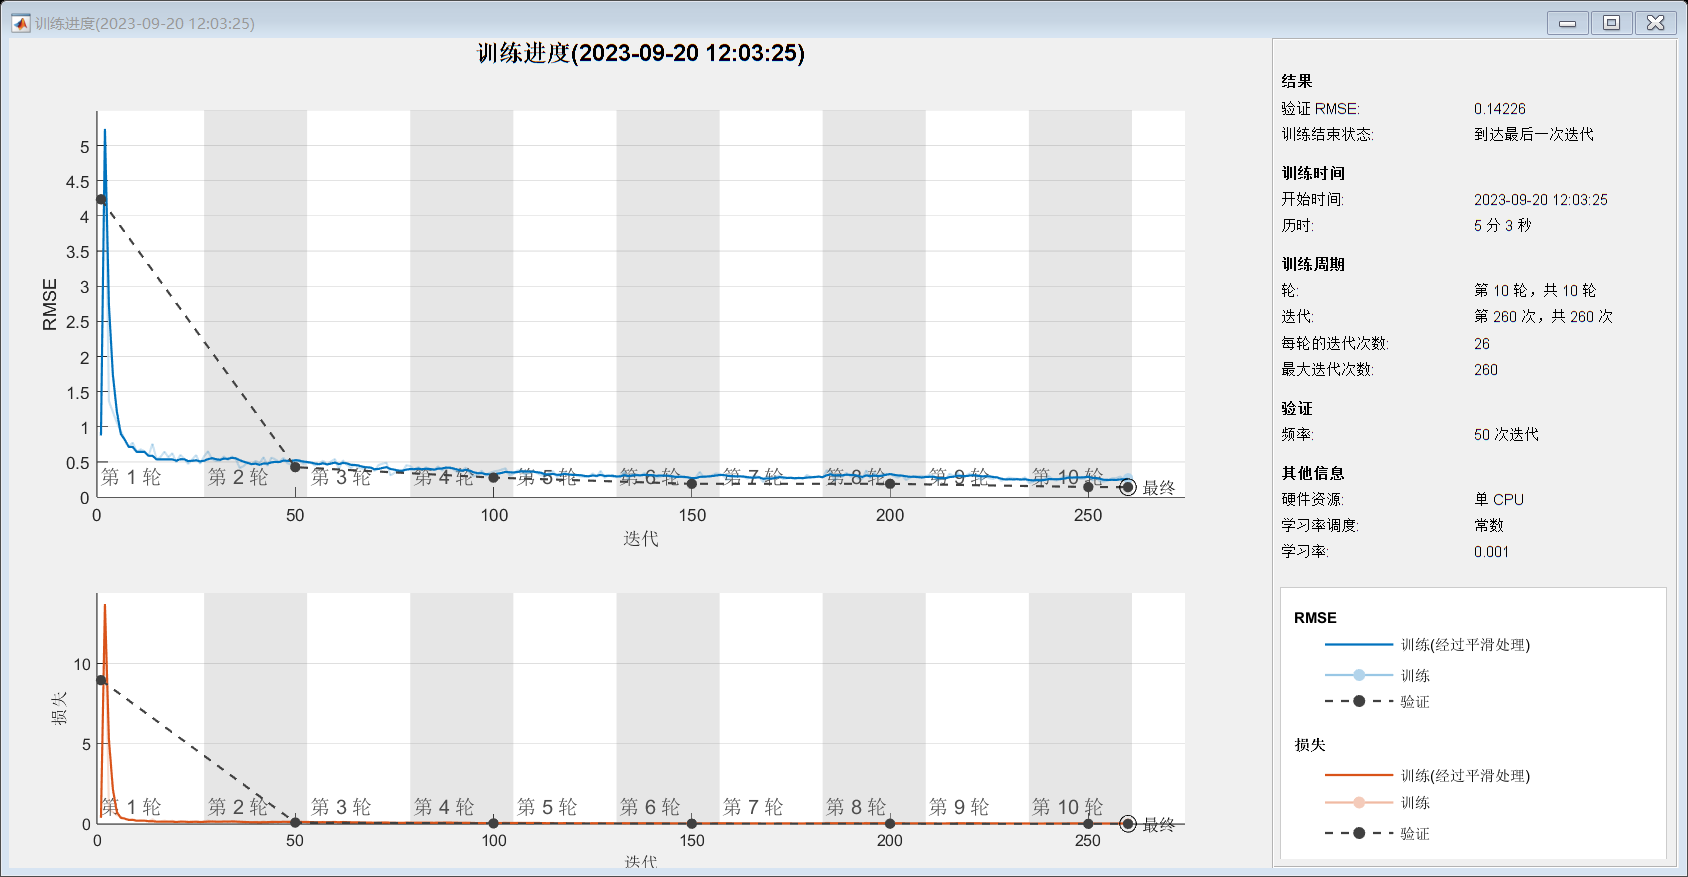


%% 训练模型
tic % 记录训练时间
model = trainNetwork(trainD, targetD', layers, options);

train_time = toc;

%% 保存模型
save(fullfile('D:\桌面\论文材料\预处理网络\CNN model', 'trainednet_regression_PRO.mat'), 'model');
save(fullfile('D:\桌面\论文材料\预处理网络\CNN model', 'output_ps_PRO.mat'), 'output_ps')

## 测试模型

load(fullfile('D:\桌面\论文材料\预处理网络\CNN model', 'trainednet_regression_PRO.mat'));
load(fullfile('D:\桌面\论文材料\预处理网络\CNN model', 'output_ps_PRO.mat'));
YPred = predict(model, testD);

%% 结果分析
% 反归一化
predict_value = mapminmax('reverse', double(YPred'),output_ps);
true_value = mapminmax('reverse', double(targetD_test), output_ps);

rmse=sqrt(mean((true_value-predict_value).^2));
disp(['根均方差(RMSE)：',num2str(rmse)])

根均方差(RMSE)：0.59886


mae=mean(abs(true_value-predict_value));
disp(['平均绝对误差（MAE）：',num2str(mae)])

平均绝对误差（MAE）：0.38872


mape=mean(abs((true_value-predict_value)./true_value));
disp(['平均相对百分误差（MAPE）：',num2str(mape*100),'%'])

平均相对百分误差（MAPE）：1602420680385035%


R2 = 1 - sum((true_value-predict_value).^2) / sum((true_value - mean(true_value)).^2)

R2 = 0.9303

disp(['The MSE of r2 is: ', num2str(R2, '%0.4f')]);

The MSE of r2 is: 0.9303


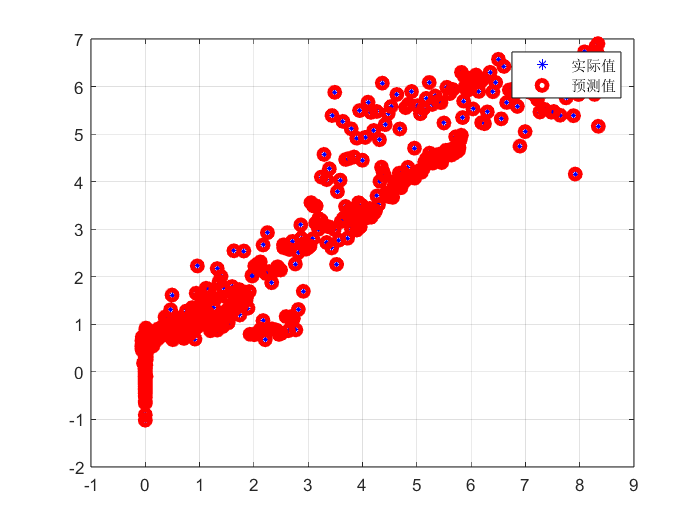


%% 绘制结果图像
YPred_train = predict(model, trainD);
YPred_train = mapminmax('reverse', double(YPred_train), output_ps);
targetD = mapminmax('reverse', double(targetD), output_ps);

figure(2)
plot(targetD,YPred_train,'b*')
hold on
plot(true_value,predict_value,'ro','linewidth',3)
legend('实际值','预测值')
grid on

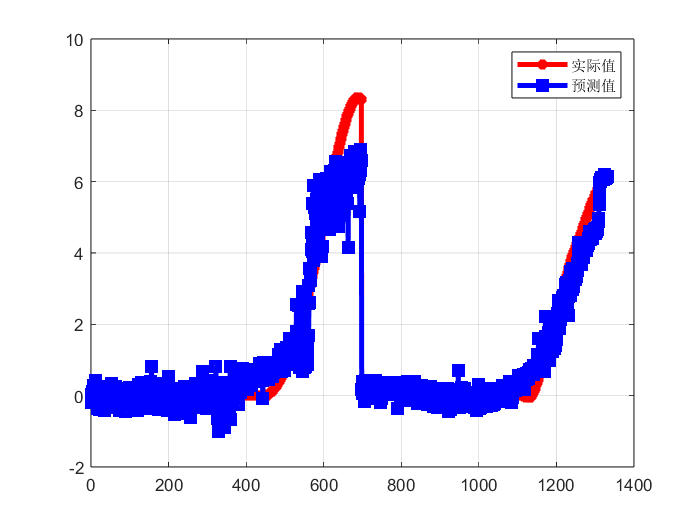


figure
plot(true_value,'-r*','linewidth',3)
hold on
plot(predict_value,'-bs','linewidth',3)
legend('实际值','预测值')
grid on

% 加载模型
load(fullfile('D:\桌面\论文材料\预处理网络\CNN model', 'trainednet_regression_PRO.mat'));
load(fullfile('D:\桌面\论文材料\预处理网络\CNN model', 'output_ps_PRO.mat'));
% 预测数据
Pred = predict(model,x_porecessD);
Pred = mapminmax('reverse', double(Pred'),output_ps);

MSE = mean((y_porcess-Pred).^2);
disp(['The MSE of SVR is: ', num2str(MSE, '%0.4f')]);

The MSE of SVR is: 5647.5040


R2 = 1 - sum((y_porcess - Pred).^2) / sum((y_porcess - mean(y_porcess)).^2)

R2 = -75.4615

disp(['The MSE of r2 is: ', num2str(R2, '%0.4f')]);

The MSE of r2 is: -75.4615


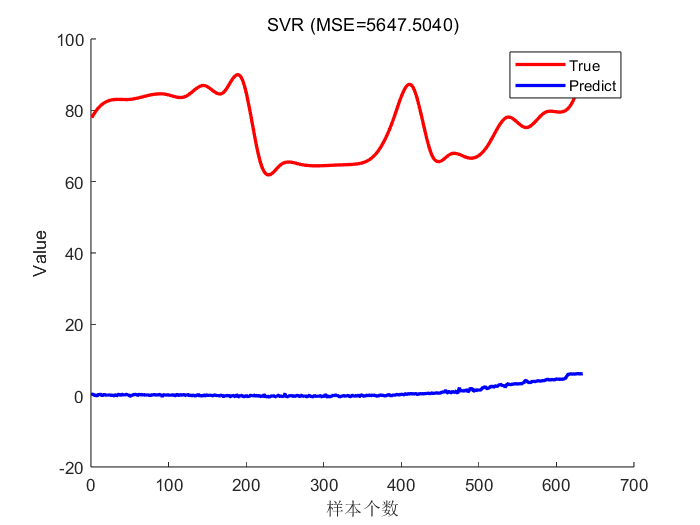

%绘制真实值和预测值的图像
figure;
hold on;
plot(y_porcess, '-r', 'LineWidth', 2);
plot(Pred, '-b', 'LineWidth', 2);
xlabel('样本个数');
ylabel('Value');
title(['SVR (MSE=', num2str(MSE, '%0.4f'), ')']);
legend('True', 'Predict');
hold off;